# Transmission

Le script suivant permet de simuler une barre de transmission et de déterminer la flèche et l'écart angulaire sur une barre en torsion. De nombreuses ameliorations peuvent etre apportees par la suite. Ce script est utile pour voir l'influence des differents parametres sur le diamètre de l'arbre.

## Hypotheses

- On se place dans le pire cas

- On suppose que les forces subit par le barre sous toute suivant l'axe y

## Parametres

% clear all
% close all
% Vehicule
g=9.81;
mvec=220; %masse véhicule
rep=0.55; % répartission masse av/ar
Kred=0.2; %rapport transmission
cmot=90000; %N.mm
s=2; %coef sécurité
L=0.5 %longeur de la barre de transmission

L = 0.5000

l1=0; %distance entre pignon et le palier
l2=0; %distance entre
Fchaine=10; %tension de la chaîne en N
Froue=g*mvec*rep/2;%effort roue sur l'arbre

%matériaux
%acier 36 Ni Cr Mo 16; X 2 Cr Ni 19-11

rho=7800;%kg/m^3
Re=[100:50:1000]%[800,180]; %Mpa ou N/mm^2

Re =          100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000


E=ones(1, length(Re))*205000;%[205000,205000];%Mpa ou N/mm^2
v=0.3;
G=E./(2*(1+v));%Mpa ou N/mm^2
Tauadm=0.5.*Re./s

Tauadm =    25.0000   37.5000   50.0000   62.5000   75.0000   87.5000  100.0000  112.5000  125.0000  137.5000  150.0000  162.5000  175.0000  187.5000  200.0000  212.5000  225.0000  237.5000  250.0000


## Torsion

Cred=cmot/Kred; %Couple au niveau de l'arbre
d=(16*Cred./(3.14.*Tauadm)).^(1/3)% diametre de l'arbre en mm

d =    45.0977   39.3965   35.7941   33.2283   31.2690   29.7029   28.4098   27.3160   26.3733   25.5486   24.8182   24.1648   23.5752   23.0392   22.5488   22.0977   21.6807   21.2935   20.9325


Alpha=32*Cred*L./(3.14.*G.*d.^(4))% écart angulaire rad

Alpha = 	1.0e+-4 *

    0.0211    0.0362    0.0531    0.0716    0.0913    0.1121    0.1339    0.1567    0.1803    0.2048    0.2300    0.2559    0.2824    0.3097    0.3375    0.3659    0.3949    0.4244    0.4544


Theta=180/3.14.*Alpha% degré

Theta =     0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0012    0.0013    0.0015    0.0016    0.0018    0.0019    0.0021    0.0023    0.0024    0.0026


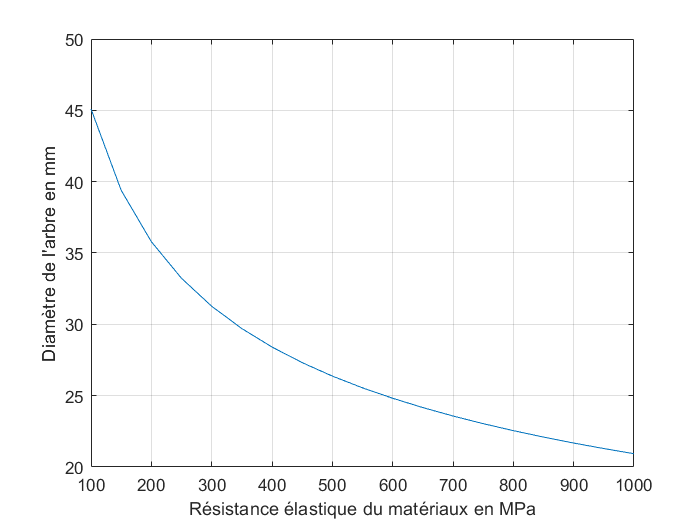

figure('Name','Choix diamètre de la transmission')
plot(Re,d)
grid()
xlabel('Résistance élastique du matériaux en MPa');
ylabel("Diamètre de l'arbre en mm");

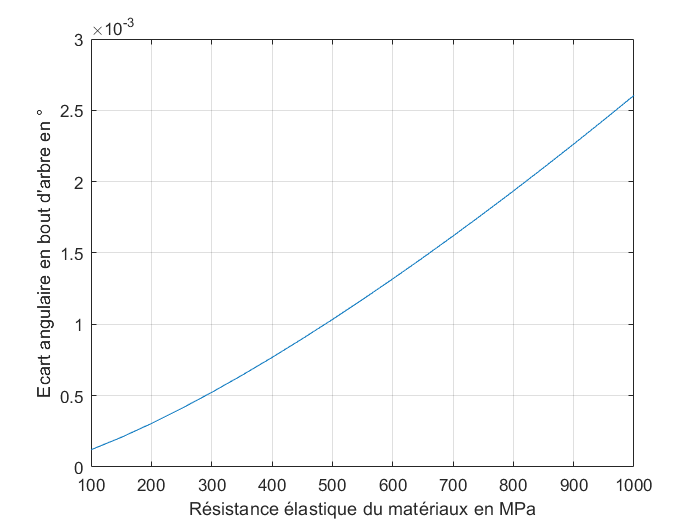


figure('Name',"Ecart angulaire en bout d'arbre")
plot(Re,Theta)
grid()
xlabel('Résistance élastique du matériaux en MPa');
ylabel("Ecart angulaire en bout d'arbre en °");

## Flexion

D=50%mm

D = 50

d=20%mm

d = 20

Igz=3.14*D^4/64;%mm^4
E=203000%MPa

E = 203000

L=0.15 %m

L = 0.1500

z=[-l1:(L+l1)/100:L]

z =    -0.0500   -0.0480   -0.0460   -0.0440   -0.0420   -0.0400   -0.0380   -0.0360   -0.0340   -0.0320   -0.0300   -0.0280   -0.0260   -0.0240   -0.0220   -0.0200   -0.0180   -0.0160   -0.0140   -0.0120   -0.0100   -0.0080   -0.0060   -0.0040   -0.0020         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480


Fchaine=100;% N
Froue=0;
Fb=mvec*g/4-Froue*(1+l2/L)

Fb = 539.5500

Fa=-Fchaine-Fb;
Mfz=zeros(1,length(z));
i=1;
Lp=-l1

Lp = -0.0500

l1=0.05;%m
m=0

m = 0

% m=rho*L*(D*10^-3)^2/4
y=zeros(1,length(z))

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


C1=(Fchaine*(l1/6)*l1^2)

C1 = 0.0021

C2=0

C2 = 0

C12=-(Fchaine*(L^3/6+l1*L^2/2)+Fa*(L^3/6))/L

C12 = 1.6483

C22=0

C22 = 0

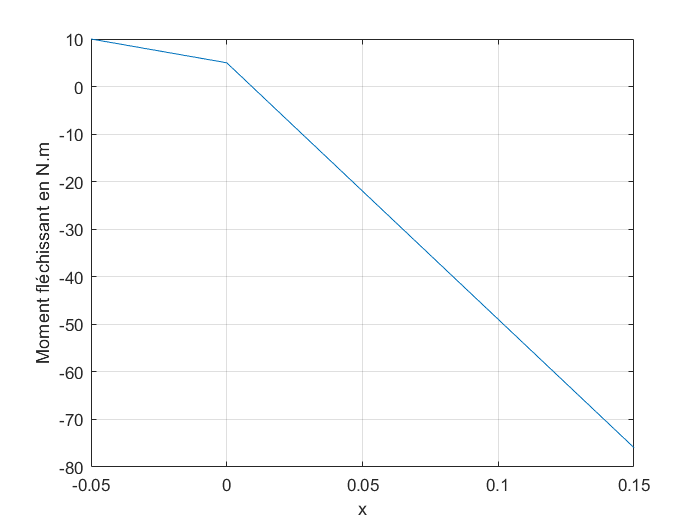

while Lp<=L+l1;
    if z(i)>=-l1 & z(i)<=0;
        Mfz(i)=-Fchaine*(z(i)-l1);
        y(i)=1/(E*Igz)*(-Fchaine*(z(i)^3/6-l1*z(i)^2/2)+C1*z(i));
    
    elseif z(i)>0;
        Mfz(i)=Fchaine*(z(i)+l1)+Fa*(z(i));
        y(i)=1/(E*Igz)*(Fchaine*(z(i)^3/6+l1*z(i)^2/2)+Fa*(z(i)^3/6)+C12*z(i)+C22);
    
    end
    i=i+1;
    Lp=(i-1)*(L+l2+l1)/100;
end

%y=(1/(E(1)*Igz).*((Fchaine+Fa)/6).*z.^3+Fchaine*l1.*z.^2-Fchaine*l1*L/2.*z-(Fchaine+Fa)*L^2/6.*z)
figure('Name','Diagramme moment fléchissant')
plot(z,Mfz)
grid()
xlabel('x');
ylabel("Moment fléchissant en N.m");

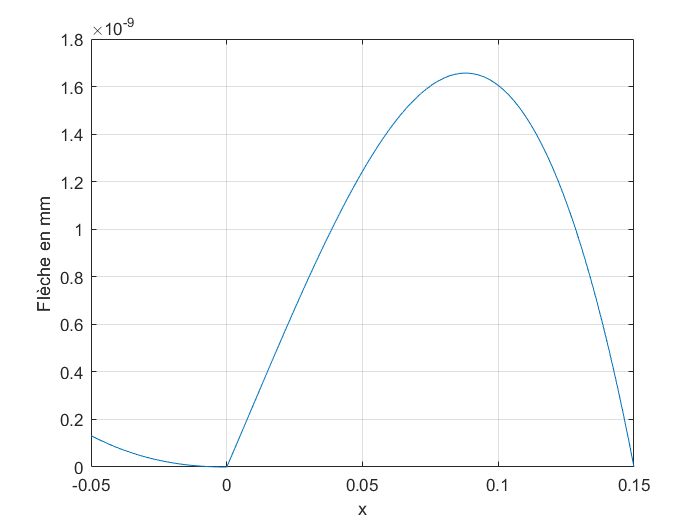


figure('Name','Flèche')
plot(z,y.*10^3)
grid()
xlabel('x');
ylabel("Flèche en mm");